Task 1

dataPath = 'C:\Users\LENOVO\Downloads\dataset1.xlsx';
dataTable = readtable(dataPath, 'Sheet', 'Qdata2');

% Handling empty cells by replacing NaN value with zeros in specific columns
nanColumns = any(ismissing(dataTable), 1);
dataTable(:, nanColumns) = fillmissing(dataTable(:, nanColumns), 'constant', 0);

% rearrange graph order - Month
monthOrder = {'Jan', 'Feb', 'Mar', 'Apr', 'May', 'Jun', 'Jul', 'Aug', 'Sep', 'Oct', 'Nov', 'Dec'};
count_date = {31, 28, 31, 30, 31, 30, 31, 31, 30, 31, 30, 31};
tblA = dataTable(:, [{'Date'} , monthOrder]);

% flatten Vector
flattenedVector = dataTable{:,monthOrder}(:)';
flattenedVector = flattenedVector(flattenedVector ~= 0);
indices = 1:numel(flattenedVector);

% Display the extracted data
% disp(tblA);

% Change format to display full decimal number
format longG;

% sum data each months as vector
total_sum = sum(tblA{:, monthOrder});

% count
total_num = numel(dataTable.Date);

% average each months
average_each_months = total_sum / total_num;

averange value each month

total_max = max(tblA{:,monthOrder});

% Display average values for each month
for i = 1:numel(monthOrder)
    max_index = find(tblA{:,monthOrder(i)} == total_max(i));
    dateOfMonth = datetime(2020, 1, 1) + days(max_index - 1);
    fprintf('%s\nAverage for %s: %.2f\nMax value : %.2f\nDate of max value: %d\n\n',monthOrder{i}, monthOrder{i}, average_each_months(i), total_max(i), dateOfMonth.Day);
end

Jan
Average for Jan: 84.81
Max value : 148.80
Date of max value: 1

Feb
Average for Feb: 82.93
Max value : 108.62
Date of max value: 2

Mar
Average for Mar: 94.15
Max value : 119.40
Date of max value: 20

□
Average for Apr
Average for Apr: 50.52
Max value : 111.56
Date of max value: 30

May
Average for May: 164.95
Max value : 334.40
Date of max value: 25

Jun
Average for Jun: 271.71
Max value : 381.50
Date of max value: 20

Jul
Average for Jul: 410.49
Max value : 750.40
Date of max value: 31

Aug
Average for Aug: 1436.63
Max value : 1714.00
Date of max value: 11

□
Average for Sep
Average for Sep: 1451.20
Max value : 1576.40
Date of max value: 1

Oct
Average for Oct: 1342.86
Max value : 1516.20
Date of max value: 1

Nov
Average for Nov: 1062.47
Max value : 1170.00
Date of max value: 1

Dec
Average for Dec: 408.49
Max value : 993.10
Date of max value: 1



Value each months

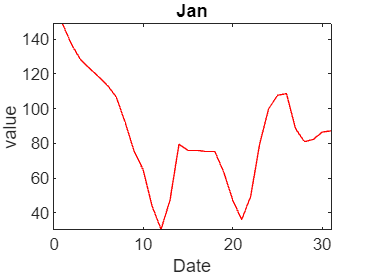

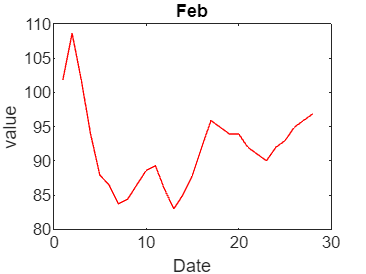

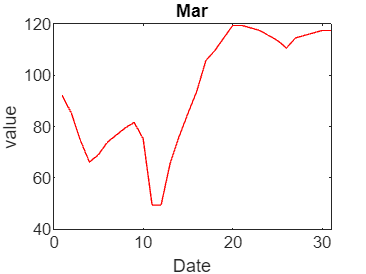

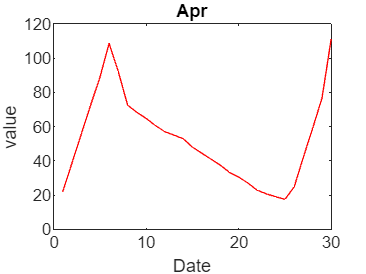

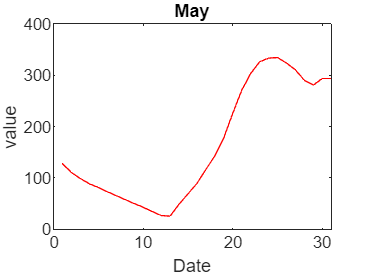

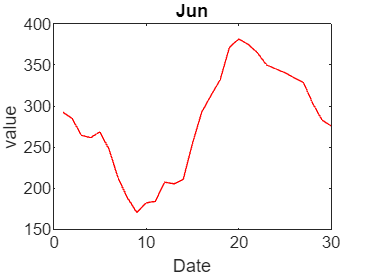

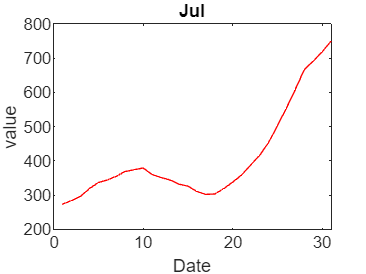

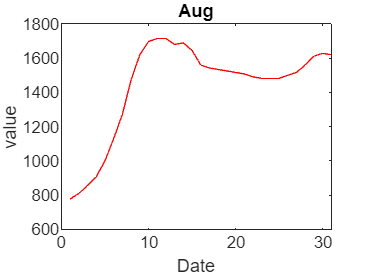

for i = 1:numel(monthOrder)
    % Create a new figure for each iteration
    figure;
    
    % Plot the data for the current month
    plot(1:count_date{i}, dataTable{1:count_date{i}, monthOrder(i)}, "r-");
    
    % Customize labels and title
    xlabel('Date');
    ylabel('value');
    title(monthOrder(i));
end

Graph annual

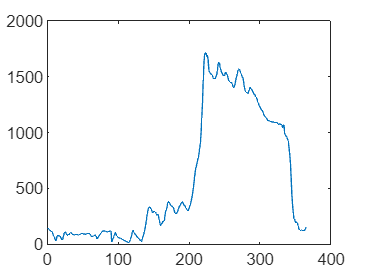

plot(indices, flattenedVector);